# 2D FEM

## Step 1 - Poisson problem on a unit square

Generate a 1x1 square mesh using GMSH (https://gmsh.info), then export it as an .m file.

 Load the mesh information by running the mesh file

square

Visualize the mesh using the trimesh function

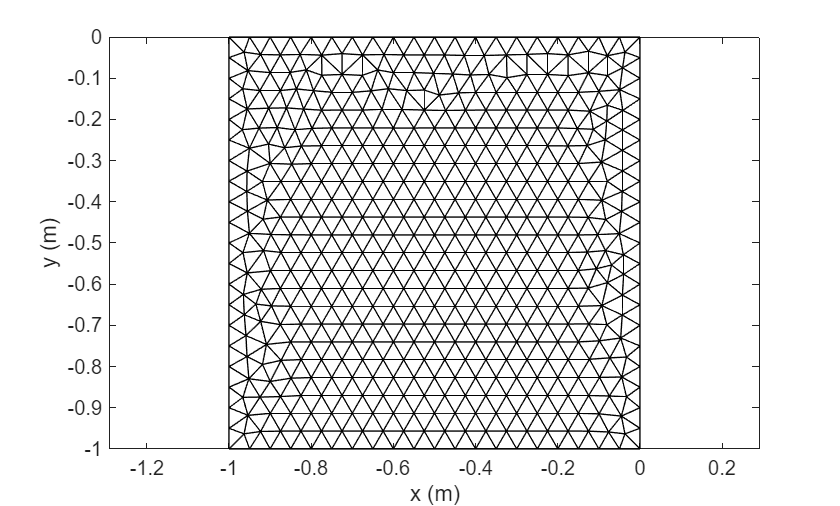

T = msh.TRIANGLES(:,1:3); % connectivity matrix
x = msh.POS(:,1); % x-coordinate of nodes
y = msh.POS(:,2); % y-coordinate of nodes

trimesh(T,x,y,"Color","K");
axis equal
xlabel('x (m)');
ylabel('y (m)');

Create a function FEM2D_s1.m that solves a basic electrostatic FEM problem on the given mesh, with Dirichlet boundary conditions on edges N and S, and Neumann boundary conditions on edges W and E.

### Computation of the shape function gradients

For a triangular element, the shape functions $L_i(x,y), \ L_j(x,y), \ L_k(x,y)$ are defined as:

$L_i(x,y) = \frac{S_i(x,y)}{S}
$;     $L_j(x,y) = \frac{S_j(x,y)}{S}
$;     $L_k(x,y) = \frac{S_k(x,y)}{S}
$


$$S =
\frac{1}{2} \mathrm{det} \left[ \matrix{
1 & x_i & y_i \cr
1 & x_j & y_j \cr
1 & x_k & y_k
}\right].
\]$$


Let's define the matrix PV:


$$[\text{PV}]=\left[ \matrix{
1 & x_i & y_i \cr
1 & x_j & y_j \cr
1 & x_k & y_k
}\right]$$


Computing the inverse of PV


$$\[
\text{PV}^{-1} =\left[
\matrix{
a_i & a_j & a_k \cr
b_i & b_j & b_k \cr
c_i & c_j & c_k
}\right]
\]$$


it can be shown that the shape function gradient matrix can be obtained taking rows 2 and 3 of inv(PV):


$$\[
[\text{\nabla L}] = \left[
\matrix{
\frac{\partial L_i}{\partial x} & \frac{\partial L_j}{\partial x} & \frac{\partial L_k}{\partial x} \cr
\frac{\partial L_i}{\partial y} & \frac{\partial L_j}{\partial y} & \frac{\partial L_k}{\partial y}
}\right] = \left[
\matrix{
b_i & b_j & b_k \cr
c_i & c_j & c_k
}\right]
=
\text{PV}^{-1}(2{:}3, :).
\]$$


Once $[\text{\nabla L}]$ is known, we can compute the $[K]_{el}$ matrix as


$$[K]_{el}=\int_{T_e}
p(x,y) [\nabla L]^T \cdot [\nabla L] \, dS$$


If $p(x,y)$ is constant over the element


$$[K]_{el}= p \, [\nabla L]^T \cdot [\nabla L] \, S$$


### Computation of the right-hand side array

Concerning the right-hand side array for $\nabla \cdot (p(x,y)\nabla \varphi )=t(x,y)$:


$$[\mathrm{rhs}]_{el} = 
\int_{T_e}{\left[ 
\matrix{
L_i(x,y) \cr
L_j(x,y) \cr
L_k(x,y) \cr
} 
\right]
t(x,y)dS$$


If $t(x,y)$ is uniform on the element


$$[\mathrm{rhs}]_{el} = t
\int_{T_e}{\left[ 
\matrix{
L_i(x,y) \cr
L_j(x,y) \cr
L_k(x,y) \cr
} 
\right]dS =  
\left[\matrix{
\frac{t}{3}S \cr
\frac{t}{3}S \cr
\frac{t}{3}S
}\right] = 
\left[\matrix{
1 \cr
1 \cr
1
}\right]
t \frac{S}{3} $$


for linear shape functions $L_i(x,y), \ L_j(x,y); \ L_k(x,y)$:


$$\matrix{
\int_{T_e} L_i(x,y) dS = \frac{1}{3} S \quad &
\int_{T_e} L_j(x,y) dS = \frac{1}{3} S \quad &
\int_{T_e} L_k(x,y) dS = \frac{1}{3} S
}$$


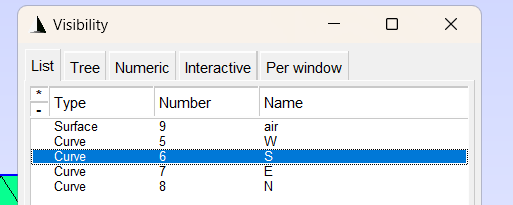

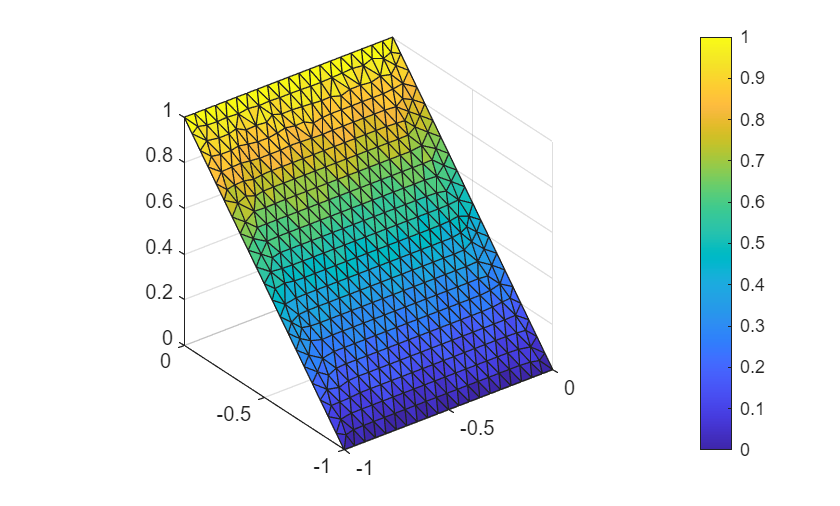

% with Dirichlet boundary conditions on edges N and S, and Neumann boundary conditions on edges W and E

% define BCs
% phi = 1 on N edge, phi = 0 on S edge
BC.D.val = [1 0];
BC.D.tag = [7 5];

% zero-gradiente (Neumann BCs) on edged E and W
BC.N.val = [0 0];
BC.N.tag = [6 8];

% define p and t
p = 1;
t = 0;

% call solver
[phi] = FEM2D_s1(msh,p,t,BC);

trisurf(T,x,y,phi)
axis equal
colorbar

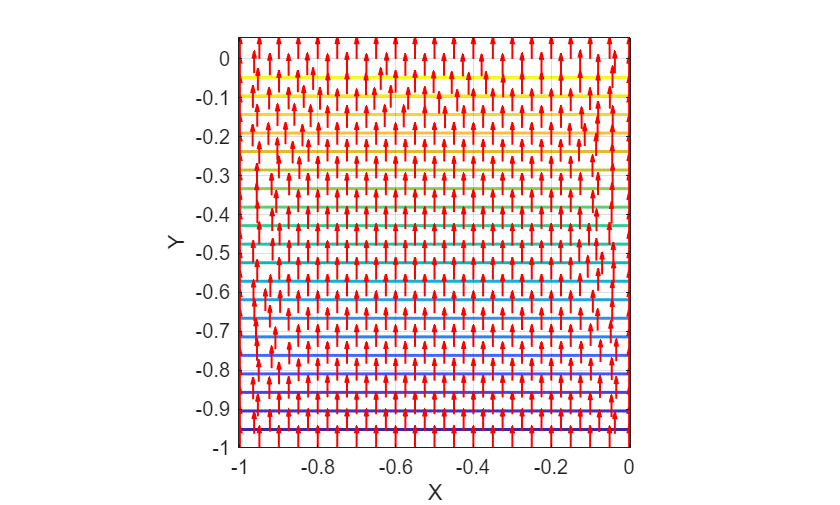

% compute the gradient of the function phi
[dphi_dx, dphi_dy] = computeGradient2D(phi, [x y], T);
visualizeFieldContour(phi, [x y], T, dphi_dx, dphi_dy)

## Step 2 - Capacitance of RG-59 coaxial cable

An RG-59 coaxial cable consists of an inner conductor having radius $R_{int} = 0.292 \ \mathrm{mm}$, an outer conductor having radius $R_{ext} = 1.855 \ \mathrm{mm}$, and a polyethylene spacing material having relative permittivity $\epsilon_r = 2.25$.

Compute the per-unit-length capacitance of the cable.

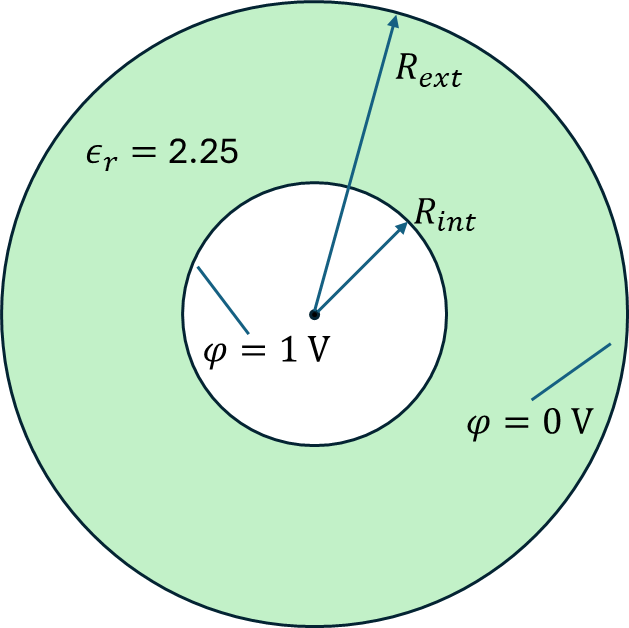

SOLUTION: C′=67.7 pF/m

Note: this problem could also be solved in 1D using cyindrical coordinates

## Step 3 - Inductance of Two Wire Single Phase Transmission Line

Consider two cylindrical conductors A and B of radius rA=rB, carrying 1 A in opposite directions. 

Conductor A is at a distance D from conductor B and both are of length L. Compute the per-unit-length inductance of the transmission line (TL).

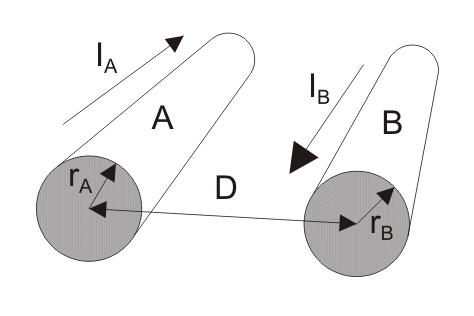

### Theory (magnetostatics $\partial/\partial t = 0$)

Starting from$\nabla \times \left(\frac{1}{\mu}\mathbf{B}\right) = \mathbf{J}$

Substituting $\(\mathbf{B} = \nabla \times \mathbf{A}\)$:


$$\nabla \times \left(\frac{1}{\mu} \nabla \times \mathbf{A}\right) = \mathbf{J}$$


 and applying the identity:


$$\nabla \times (\nabla \times \mathbf{U}) = \nabla (\nabla \cdot \mathbf{U}) - \nabla^2 \mathbf{U}$$


For magnetostatics, using the Couloumb gauge $\(\nabla \cdot \mathbf{A} = 0\)$ and using $\nabla^2 \mathbf{U} = \nabla\cdot(\nabla \mathbf{U})$one has:


$$\[
\nabla\cdot\left(\frac{1}{\mu} \nabla \mathbf{A} \right)= -\mathbf{J}
\]$$


The currents flow into/out of the $z-$plane, hence $\mathbf{A} = A_z(x,y) \mathbf{\hat{k}}$ and $\mathbf{J} = J_z(x,y) \mathbf{\hat{k}}$:

$\nabla\cdot\left(\frac{1}{\mu_r} \nabla A_z \right)= - \mu_0 J_z$    Poisson-type equation for vector potential (z-component).

Note that the equation has the same shape (and **weak formulation**) as the well known prototype


$$\nabla \cdot \left(p(x,y) \nabla \varphi\right) = t(x,y),$$


with:


$$p(x,y) \longrightarrow \frac{1}{\mu_r} \qquad \varphi(x,y) \longrightarrow A_z(x,y) \qquad t(x,y) \longrightarrow -\mu_0 J_z(x,y)$$


### Strategy

The idea is to compute the inductance using $W_m = \frac{1}{2}LI^2 \longrightarrow L=\frac{2 W_m}{I^2}$

We therefore need to compute the magnetic energy stored in the system (we need $\mathbf{B}(x,y)$).

Create and visualize mesh:

% run TL.m

% visualize mesh

### Problem setup

Define current density on TL conductors (radius $r=r_A=r_B$) to obtain unit current


$$J_z = \frac{I}{\pi r^2} \quad \text{(for conductor A)}$$



$$J_z = -\frac{I}{\pi r^2} \quad \text{(for conductor B)}$$


% def Jz

Define uniform values of $p(x,y) \rightarrow \frac{1}{\mu_r}$ and $t(x,y) \rightarrow -\mu_0 J_z$ on each of the three regions.

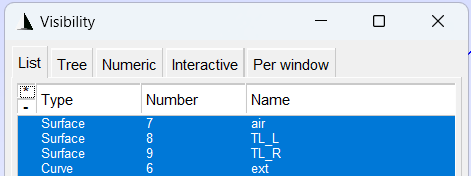

% set BCs

% compute Az

Now we need to compute $B_x(x,y)\mathbf{\hat{i}}$ and $B_y(x,y)\mathbf{\hat{j}}$.

The gradient of $A_z
$ within an element is constant and given by:


$$\[
B_x = -\frac{\partial A_z}{\partial y}, \quad
B_y = \frac{\partial A_z}{\partial x}
\]$$


% compute gradient of phi with "computeGradient2D" function

% visualize the gradient with "visualizeFieldContour" function

### Inductance computation

Compute magnetic energy over each element


$$W_{m_{el}} = \int_{T_e} \frac{1}{2 \mu} \left( B_x^2 + B_y^2 \right) \, d\Omega$$



$$W_{m_{el}} = \frac{1}{2 \mu} |\mathbf{B}|^2 \cdot \text{Area}_\text{el}$$


% we need Bx and By at element barycenter
% ...
% compute element magnetic energy 
% ...

Total magnetic energy:


$$W_m = \sum_{\text{elements}} W_{m,\text{el}}$$


% compute total magnetic energy
% ...

From energy density, compute inducance:


$$W_m = \frac{1}{2}LI^2 \qquad \longrightarrow \qquad L=\frac{2 W_m}{I^2}$$


Compare to analytical expression $L=\frac{\mu_0}{\pi}\ln{\left(\frac{D}{r}\right)} \quad [\mathrm{H/m}]$:

Try to increase the radius of the external domain, and refine a bit the mesh. The agreement should improve!